clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[2.54;8.05;4.79];
u31=[0.715;-0.531;-0.455];
r2=[2.92;-0.225;4.79];
u32=[0.715;-0.531;-0.455];
r3=[2.16;16.32;4.79];
u33=[0.715;-0.531;-0.455];
r4=[0.714;7.60;14.37];
u34=[0.715;-0.531;-0.455];
r5=[10.20;8.05;4.79];
u35=[0.715;-0.531;-0.455];
r6=[1.10;-0.675;14.37];
u36=[0.715;-0.531;-0.455];
r7=[0.332;15.88;14.37];
u37=[0.715;-0.531;-0.455];
r8=[10.585;-0.225;4.79];
u38=[0.715;-0.531;-0.455];
r9=[9.82;16.32;4.79];
u39=[0.715;-0.531;-0.455];
r10=[8.38;7.60;14.37];
u310=[0.715;-0.531;-0.455];
r11=[8.76;-0.675;14.37];
u311=[0.715;-0.531;-0.455];
r12=[7.996;15.875;14.37];
u312=[0.715;-0.531;-0.455];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];
x10=[];
y10=[];
x11=[];
y11=[];
x12=[];
y12=[];
x13=[];
y13=[];

hold on 
axis([3 20 0 22]);
for R1=4:0.3:15 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     4.0000    4.5000    1.0008


ans =     4.3000    3.8500    1.0006


ans =     4.6000    3.4500    1.0108


ans =     4.9000    3.2500    1.0031


ans =     5.2000    3.0500    1.0183


ans =     5.5000    2.9500    1.0127


ans =     5.8000    2.8500    1.0184


ans =     6.1000    2.8000    1.0092


ans =     6.4000    2.7500    1.0059


ans =     6.7000    2.7000    1.0078


ans =     7.0000    2.6500    1.0144


ans =     7.3000    2.6000    1.0254


ans =     7.6000    2.6000    1.0084


ans =     7.9000    2.5500    1.0253


ans =     8.2000    2.5500    1.0119


ans =     8.5000    2.5000    1.0338


ans =     8.8000    2.5000    1.0230


ans =     9.1000    2.5000    1.0132


ans =     9.4000    2.5000    1.0044


ans =     9.7000    2.4500    1.0325


ans =    10.0000    2.4500    1.0252


ans =    10.3000    2.4500    1.0186


ans =    10.6000    2.4500    1.0125


ans =    10.9000    2.4500    1.0070


ans =    11.2000    2.4500    1.0019


ans =    11.5000    2.4000    1.0355


ans =    11.8000    2.4000    1.0312


ans =    12.1000    2.4000    1.0272


ans =    12.4000    2.4000    1.0235


ans =    12.7000    2.4000    1.0201


ans =    13.0000    2.4000    1.0169


ans =    13.3000    2.4000    1.0139


ans =    13.6000    2.4000    1.0112


ans =    13.9000    2.4000    1.0086


ans =    14.2000    2.4000    1.0062


ans =    14.5000    2.4000    1.0040


ans =    14.8000    2.4000    1.0019



scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')


for R3=3:0.3:15 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =     9.5000    3.0000    1.0009


ans =     7.1000    3.3000    1.0027


ans =     6.1500    3.6000    1.0033


ans =     5.6000    3.9000    1.0090


ans =     5.3000    4.2000    1.0035


ans =     5.0500    4.5000    1.0092


ans =     4.9000    4.8000    1.0053


ans =     4.7500    5.1000    1.0129


ans =     4.6500    5.4000    1.0140


ans =     4.6000    5.7000    1.0048


ans =     4.5000    6.0000    1.0177


ans =     4.4500    6.3000    1.0171


ans =     4.4500    6.6000    1.0006


ans = 1×3
    4.4000    6.9000    1.0053


ans = 1×3
    4.3500    7.2000    1.0123


ans = 1×3
    4.3500    7.5000    1.0012


ans = 1×3
    4.3000    7.8000    1.0117


ans = 1×3
    4.3000    8.1000    1.0029


ans = 1×3
    4.2500    8.4000    1.0161


ans = 1×3
    4.2500    8.7000    1.0090


ans = 1×3
    4.2500    9.0000    1.0027


ans = 1×3
    4.2000    9.3000    1.0187


ans = 1×3
    4.2000    9.6000    1.0135


ans = 1×3
    4.2000    9.9000    1.0087


ans = 1×3
    4.2000   10.2000    1.0044


ans = 1×3
    4.2000   10.5000    1.0004


ans = 1×3
    4.1500   10.8000    1.0194


ans = 1×3
    4.1500   11.1000    1.0160


ans = 1×3
    4.1500   11.4000    1.0129


ans = 1×3
    4.1500   11.7000    1.0101


ans = 1×3
    4.1500   12.0000    1.0074


ans = 1×3
    4.1500   12.3000    1.0049


ans = 1×3
    4.1500   12.6000    1.0026


ans = 1×3
    4.1500   12.9000    1.0005


ans = 1×3
    4.1000   13.2000    1.0220


ans = 1×3
    4.1000   13.5000    1.0201


ans = 1×3
    4.1000   13.8000    1.0184


ans = 1×3
    4.1000   14.1000    1.0168


ans = 1×3
    4.1000   14.4000    1.0153


ans = 1×3
    4.1000   14.7000    1.0138


ans = 1×3
    4.1000   15.0000    1.0125


scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','14')

for R1=4:0.3:15 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
    4.0000    3.6500    1.0110


ans = 1×3
    4.3000    3.4500    1.0178


ans = 1×3
    4.6000    3.3500    1.0071


ans = 1×3
    4.9000    3.2500    1.0086


ans = 1×3
    5.2000    3.1500    1.0210


ans = 1×3
    5.5000    3.1000    1.0175


ans = 1×3
    5.8000    3.0500    1.0194


ans = 1×3
    6.1000    3.0000    1.0261


ans = 1×3
    6.4000    3.0000    1.0085


ans = 1×3
    6.7000    2.9500    1.0217


ans = 1×3
    7.0000    2.9500    1.0084


ans = 1×3
    7.3000    2.9000    1.0267


ans = 1×3
    7.6000    2.9000    1.0163


ans = 1×3
    7.9000    2.9000    1.0071


ans = 1×3
    8.2000    2.8500    1.0305


ans = 1×3
    8.5000    2.8500    1.0232


ans = 1×3
    8.8000    2.8500    1.0166


ans = 1×3
    9.1000    2.8500    1.0106


ans = 1×3
    9.4000    2.8500    1.0053


ans = 1×3
    9.7000    2.8500    1.0004


ans = 1×3
   10.0000    2.8000    1.0293


ans = 1×3
   10.3000    2.8000    1.0253


ans = 1×3
   10.6000    2.8000    1.0216


ans = 1×3
   10.9000    2.8000    1.0182


ans = 1×3
   11.2000    2.8000    1.0151


ans = 1×3
   11.5000    2.8000    1.0122


ans = 1×3
   11.8000    2.8000    1.0096


ans = 1×3
   12.1000    2.8000    1.0072


ans = 1×3
   12.4000    2.8000    1.0049


ans = 1×3
   12.7000    2.8000    1.0029


ans = 1×3
   13.0000    2.8000    1.0009


ans = 1×3
   13.3000    2.7500    1.0344


ans = 1×3
   13.6000    2.7500    1.0327


ans = 1×3
   13.9000    2.7500    1.0312


ans = 1×3
   14.2000    2.7500    1.0298


ans = 1×3
   14.5000    2.7500    1.0284


ans = 1×3
   14.8000    2.7500    1.0272



scatter(x3,y3,10,'markerfacecolor',[63, 125, 162]/256,...
        'markeredgecolor',[63, 125, 162]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','15')

for R3=2:0.3:15 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans = 1×3
    6.6000    2.0000    1.0080


ans = 1×3
    6.5500    2.3000    1.0141


ans = 1×3
    6.5500    2.6000    1.0083


ans = 1×3
    6.5500    2.9000    1.0041


ans = 1×3
    6.5500    3.2000    1.0011


ans = 1×3
    6.5000    3.5000    1.0140


ans = 1×3
    6.5000    3.8000    1.0123


ans = 1×3
    6.5000    4.1000    1.0109


ans = 1×3
    6.5000    4.4000    1.0098


ans = 1×3
    6.5000    4.7000    1.0089


ans = 1×3
    6.5000    5.0000    1.0081


ans = 1×3
    6.5000    5.3000    1.0075


ans = 1×3
    6.5000    5.6000    1.0069


ans = 1×3
    6.5000    5.9000    1.0065


ans = 1×3
    6.5000    6.2000    1.0061


ans = 1×3
    6.5000    6.5000    1.0058


ans = 1×3
    6.5000    6.8000    1.0055


ans = 1×3
    6.5000    7.1000    1.0052


ans = 1×3
    6.5000    7.4000    1.0050


ans = 1×3
    6.5000    7.7000    1.0048


ans = 1×3
    6.5000    8.0000    1.0046


ans = 1×3
    6.5000    8.3000    1.0045


ans = 1×3
    6.5000    8.6000    1.0043


ans = 1×3
    6.5000    8.9000    1.0042


ans = 1×3
    6.5000    9.2000    1.0041


ans = 1×3
    6.5000    9.5000    1.0040


ans = 1×3
    6.5000    9.8000    1.0039


ans = 1×3
    6.5000   10.1000    1.0038


ans = 1×3
    6.5000   10.4000    1.0037


ans = 1×3
    6.5000   10.7000    1.0036


ans = 1×3
    6.5000   11.0000    1.0036


ans = 1×3
    6.5000   11.3000    1.0035


ans = 1×3
    6.5000   11.6000    1.0035


ans = 1×3
    6.5000   11.9000    1.0034


ans = 1×3
    6.5000   12.2000    1.0034


ans = 1×3
    6.5000   12.5000    1.0033


ans = 1×3
    6.5000   12.8000    1.0033


ans = 1×3
    6.5000   13.1000    1.0032


ans = 1×3
    6.5000   13.4000    1.0032


ans = 1×3
    6.5000   13.7000    1.0032


ans = 1×3
    6.5000   14.0000    1.0031


ans = 1×3
    6.5000   14.3000    1.0031


ans = 1×3
    6.5000   14.6000    1.0031


ans = 1×3
    6.5000   14.9000    1.0030



scatter(x4,y4,10,'markerfacecolor',[239, 193, 48]/256,...
        'markeredgecolor',[239, 193, 48]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','16')

for R1=4:0.3:15 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    4.0000   14.3000    1.0004


ans = 1×3
    4.3000   10.2500    1.0004


ans = 1×3
    4.6000    8.6500    1.0027


ans = 1×3
    4.9000    7.8000    1.0024


ans = 1×3
    5.2000    7.2500    1.0029


ans = 1×3
    5.5000    6.8500    1.0062


ans = 1×3
    5.8000    6.6000    1.0014


ans = 1×3
    6.1000    6.3500    1.0084


ans = 1×3
    6.4000    6.2000    1.0049


ans = 1×3
    6.7000    6.0500    1.0082


ans = 1×3
    7.0000    5.9500    1.0056


ans = 1×3
    7.3000    5.8500    1.0074


ans = 1×3
    7.6000    5.8000    1.0000


ans = 1×3
    7.9000    5.7000    1.0087


ans = 1×3
    8.2000    5.6500    1.0066


ans = 1×3
    8.5000    5.6000    1.0065


ans = 1×3
    8.8000    5.5500    1.0082


ans = 1×3
    9.1000    5.5000    1.0116


ans = 1×3
    9.4000    5.5000    1.0010


ans = 1×3
    9.7000    5.4500    1.0069


ans = 1×3
   10.0000    5.4000    1.0140


ans = 1×3
   10.3000    5.4000    1.0060


ans = 1×3
   10.6000    5.3500    1.0151


ans = 1×3
   10.9000    5.3500    1.0083


ans = 1×3
   11.2000    5.3500    1.0021


ans = 1×3
   11.5000    5.3000    1.0133


ans = 1×3
   11.8000    5.3000    1.0080


ans = 1×3
   12.1000    5.3000    1.0031


ans = 1×3
   12.4000    5.2500    1.0159


ans = 1×3
   12.7000    5.2500    1.0117


ans = 1×3
   13.0000    5.2500    1.0077


ans = 1×3
   13.3000    5.2500    1.0041


ans = 1×3
   13.6000    5.2500    1.0006


ans = 1×3
   13.9000    5.2000    1.0153


ans = 1×3
   14.2000    5.2000    1.0123


ans = 1×3
   14.5000    5.2000    1.0095


ans = 1×3
   14.8000    5.2000    1.0069


scatter(x5,y5,10,'markerfacecolor',[151, 150, 159]/256,...
        'markeredgecolor',[151, 150, 159]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','17')

for R1=4:0.3:15 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];  
end

ans = 1×3
    4.0000    6.9500    1.0056


ans = 1×3
    4.3000    6.5500    1.0090


ans = 1×3
    4.6000    6.3000    1.0059


ans = 1×3
    4.9000    6.1000    1.0067


ans = 1×3
    5.2000    5.9500    1.0067


ans = 1×3
    5.5000    5.8500    1.0020


ans = 1×3
    5.8000    5.7500    1.0032


ans = 1×3
    6.1000    5.6500    1.0095


ans = 1×3
    6.4000    5.6000    1.0053


ans = 1×3
    6.7000    5.5500    1.0040


ans = 1×3
    7.0000    5.5000    1.0052


ans = 1×3
    7.3000    5.4500    1.0084


ans = 1×3
    7.6000    5.4000    1.0136


ans = 1×3
    7.9000    5.4000    1.0038


ans = 1×3
    8.2000    5.3500    1.0117


ans = 1×3
    8.5000    5.3500    1.0039


ans = 1×3
    8.8000    5.3000    1.0140


ans = 1×3
    9.1000    5.3000    1.0077


ans = 1×3
    9.4000    5.3000    1.0019


ans = 1×3
    9.7000    5.2500    1.0143


ans = 1×3
   10.0000    5.2500    1.0096


ans = 1×3
   10.3000    5.2500    1.0052


ans = 1×3
   10.6000    5.2500    1.0013


ans = 1×3
   10.9000    5.2000    1.0157


ans = 1×3
   11.2000    5.2000    1.0124


ans = 1×3
   11.5000    5.2000    1.0093


ans = 1×3
   11.8000    5.2000    1.0064


ans = 1×3
   12.1000    5.2000    1.0038


ans = 1×3
   12.4000    5.2000    1.0014


ans = 1×3
   12.7000    5.1500    1.0177


ans = 1×3
   13.0000    5.1500    1.0156


ans = 1×3
   13.3000    5.1500    1.0136


ans = 1×3
   13.6000    5.1500    1.0118


ans = 1×3
   13.9000    5.1500    1.0101


ans = 1×3
   14.2000    5.1500    1.0085


ans = 1×3
   14.5000    5.1500    1.0070


ans = 1×3
   14.8000    5.1500    1.0055



scatter(x6,y6,10,'markerfacecolor',[237, 125, 49]/256,...
        'markeredgecolor',[237, 125, 49]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','18')

for R3=1:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r9,R1,R3,u31,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];  
end

ans = 1×3
    6.0000    1.0000    1.0046


ans = 1×3
    5.7500    1.3000    1.0110


ans = 1×3
    5.6500    1.6000    1.0102


ans = 1×3
    5.6000    1.9000    1.0083


ans = 1×3
    5.5500    2.2000    1.0141


ans = 1×3
    5.5500    2.5000    1.0064


ans = 1×3
    5.5500    2.8000    1.0010


ans = 1×3
    5.5000    3.1000    1.0150


ans = 1×3
    5.5000    3.4000    1.0121


ans = 1×3
    5.5000    3.7000    1.0099


ans = 1×3
    5.5000    4.0000    1.0081


ans = 1×3
    5.5000    4.3000    1.0067


ans = 1×3
    5.5000    4.6000    1.0056


ans = 1×3
    5.5000    4.9000    1.0047


ans = 1×3
    5.5000    5.2000    1.0039


ans = 1×3
    5.5000    5.5000    1.0032


ans = 1×3
    5.5000    5.8000    1.0027


ans = 1×3
    5.5000    6.1000    1.0022


ans = 1×3
    5.5000    6.4000    1.0018


ans = 1×3
    5.5000    6.7000    1.0014


ans = 1×3
    5.5000    7.0000    1.0011


ans = 1×3
    5.5000    7.3000    1.0009


ans = 1×3
    5.5000    7.6000    1.0006


ans = 1×3
    5.5000    7.9000    1.0004


ans = 1×3
    5.5000    8.2000    1.0002


ans = 1×3
    5.5000    8.5000    1.0001


ans = 1×3
    5.4500    8.8000    1.0183


ans = 1×3
    5.4500    9.1000    1.0182


ans = 1×3
    5.4500    9.4000    1.0180


ans = 1×3
    5.4500    9.7000    1.0179


ans = 1×3
    5.4500   10.0000    1.0178


ans = 1×3
    5.4500   10.3000    1.0177


ans = 1×3
    5.4500   10.6000    1.0176


ans = 1×3
    5.4500   10.9000    1.0175


ans = 1×3
    5.4500   11.2000    1.0175


ans = 1×3
    5.4500   11.5000    1.0174


ans = 1×3
    5.4500   11.8000    1.0173


ans = 1×3
    5.4500   12.1000    1.0173


ans = 1×3
    5.4500   12.4000    1.0172


ans = 1×3
    5.4500   12.7000    1.0172


ans = 1×3
    5.4500   13.0000    1.0171



scatter(x7,y7,10,'markerfacecolor',[47, 85, 151]/256,...
        'markeredgecolor',[47, 85, 151]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','19')

for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r10,R1,R3,u31,u310);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];  
end

ans = 1×3
    5.6000    2.0000    1.0053


ans = 1×3
    5.6000    2.3000    1.0053


ans = 1×3
    5.6000    2.6000    1.0052


ans = 1×3
    5.6000    2.9000    1.0052


ans = 1×3
    5.6000    3.2000    1.0052


ans = 1×3
    5.6000    3.5000    1.0052


ans = 1×3
    5.6000    3.8000    1.0052


ans = 1×3
    5.6000    4.1000    1.0052


ans = 1×3
    5.6000    4.4000    1.0052


ans = 1×3
    5.6000    4.7000    1.0051


ans = 1×3
    5.6000    5.0000    1.0051


ans = 1×3
    5.6000    5.3000    1.0051


ans = 1×3
    5.6000    5.6000    1.0051


ans = 1×3
    5.6000    5.9000    1.0051


ans = 1×3
    5.6000    6.2000    1.0051


ans = 1×3
    5.6000    6.5000    1.0051


ans = 1×3
    5.6000    6.8000    1.0051


ans = 1×3
    5.6000    7.1000    1.0051


ans = 1×3
    5.6000    7.4000    1.0051


ans = 1×3
    5.6000    7.7000    1.0051


ans = 1×3
    5.6000    8.0000    1.0051


ans = 1×3
    5.6000    8.3000    1.0051


ans = 1×3
    5.6000    8.6000    1.0051


ans = 1×3
    5.6000    8.9000    1.0051


ans = 1×3
    5.6000    9.2000    1.0051


ans = 1×3
    5.6000    9.5000    1.0051


ans = 1×3
    5.6000    9.8000    1.0051


ans = 1×3
    5.6000   10.1000    1.0051


ans = 1×3
    5.6000   10.4000    1.0051


ans = 1×3
    5.6000   10.7000    1.0051


ans = 1×3
    5.6000   11.0000    1.0051


ans = 1×3
    5.6000   11.3000    1.0051


ans = 1×3
    5.6000   11.6000    1.0051


ans = 1×3
    5.6000   11.9000    1.0051


ans = 1×3
    5.6000   12.2000    1.0051


ans = 1×3
    5.6000   12.5000    1.0051


ans = 1×3
    5.6000   12.8000    1.0051


scatter(x8,y8,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','1,10')

for R1=7:0.3:15 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r11,R1,R3,u31,u311);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    [R1,R3,miu2]
    x9=[x9,R1];
    y9=[y9,R3];  
end

ans = 1×3
    7.0000    9.6500    1.0001


ans = 1×3
    7.3000    6.4000    1.0007


ans = 1×3
    7.6000    5.2000    1.0038


ans = 1×3
    7.9000    4.6000    1.0017


ans = 1×3
    8.2000    4.2000    1.0012


ans = 1×3
    8.5000    3.9000    1.0042


ans = 1×3
    8.8000    3.7000    1.0022


ans = 1×3
    9.1000    3.5000    1.0116


ans = 1×3
    9.4000    3.4000    1.0038


ans = 1×3
    9.7000    3.3000    1.0018


ans = 1×3
   10.0000    3.2000    1.0054


ans = 1×3
   10.3000    3.1000    1.0148


ans = 1×3
   10.6000    3.0500    1.0098


ans = 1×3
   10.9000    3.0000    1.0077


ans = 1×3
   11.2000    2.9500    1.0085


ans = 1×3
   11.5000    2.9000    1.0120


ans = 1×3
   11.8000    2.8500    1.0181


ans = 1×3
   12.1000    2.8500    1.0020


ans = 1×3
   12.4000    2.8000    1.0118


ans = 1×3
   12.7000    2.7500    1.0241


ans = 1×3
   13.0000    2.7500    1.0111


ans = 1×3
   13.3000    2.7000    1.0267


ans = 1×3
   13.6000    2.7000    1.0155


ans = 1×3
   13.9000    2.7000    1.0049


ans = 1×3
   14.2000    2.6500    1.0243


ans = 1×3
   14.5000    2.6500    1.0151


ans = 1×3
   14.8000    2.6500    1.0064



for R3=5:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r11,R1,R3,u31,u311);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    [R1,R3,miu2]
    x9=[x9,R1];
    y9=[y9,R3];  
end

ans = 1×3
    7.7000    5.0000    1.0000


ans = 1×3
    7.5500    5.3000    1.0067


ans = 1×3
    7.4500    5.6000    1.0079


ans = 1×3
    7.4000    5.9000    1.0015


ans = 1×3
    7.3000    6.2000    1.0096


ans = 1×3
    7.2500    6.5000    1.0085


ans = 1×3
    7.2000    6.8000    1.0093


ans = 1×3
    7.1500    7.1000    1.0118


ans = 1×3
    7.1500    7.4000    1.0030


ans = 1×3
    7.1000    7.7000    1.0080


ans = 1×3
    7.1000    8.0000    1.0011


ans = 1×3
    7.0500    8.3000    1.0079


ans = 1×3
    7.0500    8.6000    1.0024


ans = 1×3
    7.0000    8.9000    1.0107


ans = 1×3
    7.0000    9.2000    1.0061


ans = 1×3
    7.0000    9.5000    1.0021


ans = 1×3
    6.9500    9.8000    1.0119


scatter(x9,y9,10,'markerfacecolor',[191, 144, 0]/256,...
        'markeredgecolor',[191, 144, 0]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','1,11')

for R3=3:0.3:13 %离心率
    R1=8;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r12,R1,R3,u31,u312);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r12,R1,R3,u31,u312);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r12,R1,R3,u31,u312);
    end
    [R1,R3,miu2]
    x10=[x10,R1];
    y10=[y10,R3];  
end

ans = 1×3
    9.9000    3.0000    1.0036


ans = 1×3
    8.8500    3.3000    1.0043


ans = 1×3
    8.2500    3.6000    1.0038


ans = 1×3
    7.8500    3.9000    1.0050


ans = 1×3
    7.6000    4.2000    1.0006


ans = 1×3
    7.4000    4.5000    1.0000


ans = 1×3
    7.2000    4.8000    1.0097


ans = 1×3
    7.1000    5.1000    1.0055


ans = 1×3
    7.0000    5.4000    1.0064


ans = 1×3
    6.9000    5.7000    1.0118


ans = 1×3
    6.8500    6.0000    1.0082


ans = 1×3
    6.8000    6.3000    1.0072


ans = 1×3
    6.7500    6.6000    1.0082


ans = 1×3
    6.7000    6.9000    1.0111


ans = 1×3
    6.7000    7.2000    1.0020


ans = 1×3
    6.6500    7.5000    1.0075


ans = 1×3
    6.6500    7.8000    1.0004


ans = 1×3
    6.6000    8.1000    1.0079


ans = 1×3
    6.6000    8.4000    1.0023


ans = 1×3
    6.5500    8.7000    1.0113


ans = 1×3
    6.5500    9.0000    1.0067


ans = 1×3
    6.5500    9.3000    1.0026


ans = 1×3
    6.5000    9.6000    1.0133


ans = 1×3
    6.5000    9.9000    1.0099


ans = 1×3
    6.5000   10.2000    1.0067


ans = 1×3
    6.5000   10.5000    1.0039


ans = 1×3
    6.5000   10.8000    1.0012


ans = 1×3
    6.4500   11.1000    1.0137


ans = 1×3
    6.4500   11.4000    1.0114


ans = 1×3
    6.4500   11.7000    1.0093


ans = 1×3
    6.4500   12.0000    1.0074


ans = 1×3
    6.4500   12.3000    1.0056


ans = 1×3
    6.4500   12.6000    1.0040


ans = 1×3
    6.4500   12.9000    1.0024



scatter(x10,y10,10,'markerfacecolor',[112, 48, 160]/256,...
        'markeredgecolor',[112, 48, 160]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','1,12')


for R1=6:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r4,r5,R1,R3,u34,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    [R1,R3,miu2]
    x11=[x11,R1];
    y11=[y11,R3];  
end

ans = 1×3
    6.0000    7.2500    1.0035


ans = 1×3
    6.3000    7.0000    1.0039


ans = 1×3
    6.6000    6.8000    1.0048


ans = 1×3
    6.9000    6.6500    1.0033


ans = 1×3
    7.2000    6.5000    1.0076


ans = 1×3
    7.5000    6.4000    1.0059


ans = 1×3
    7.8000    6.3000    1.0080


ans = 1×3
    8.1000    6.2500    1.0012


ans = 1×3
    8.4000    6.1500    1.0093


ans = 1×3
    8.7000    6.1000    1.0071


ans = 1×3
    9.0000    6.0500    1.0067


ans = 1×3
    9.3000    6.0000    1.0079


ans = 1×3
    9.6000    5.9500    1.0106


ans = 1×3
    9.9000    5.9500    1.0004


ans = 1×3
   10.2000    5.9000    1.0054


ans = 1×3
   10.5000    5.8500    1.0115


ans = 1×3
   10.8000    5.8500    1.0037


ans = 1×3
   11.1000    5.8000    1.0116


ans = 1×3
   11.4000    5.8000    1.0049


ans = 1×3
   11.7000    5.7500    1.0142


ans = 1×3
   12.0000    5.7500    1.0086


ans = 1×3
   12.3000    5.7500    1.0033


ans = 1×3
   12.6000    5.7000    1.0143


ans = 1×3
   12.9000    5.7000    1.0097



scatter(x11,y11,10,'markerfacecolor',[132, 60, 12]/256,...
        'markeredgecolor',[132, 60, 12]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','45')


for R1=4:0.3:13 %离心率
    R3=7;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r4,r8,R1,R3,u34,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r4,r8,R1,R3,u34,u38);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r4,r8,R1,R3,u34,u38);
    end
    [R1,R3,miu2]
    x12=[x12,R1];
    y12=[y12,R3];  
end

ans = 1×3
    4.0000    8.3000    1.0046


ans = 1×3
    4.3000    8.2000    1.0094


ans = 1×3
    4.6000    8.1500    1.0069


ans = 1×3
    4.9000    8.1000    1.0070


ans = 1×3
    5.2000    8.0500    1.0092


ans = 1×3
    5.5000    8.0500    1.0013


ans = 1×3
    5.8000    8.0000    1.0064


ans = 1×3
    6.1000    8.0000    1.0007


ans = 1×3
    6.4000    7.9500    1.0078


ans = 1×3
    6.7000    7.9500    1.0035


ans = 1×3
    7.0000    7.9000    1.0120


ans = 1×3
    7.3000    7.9000    1.0087


ans = 1×3
    7.6000    7.9000    1.0058


ans = 1×3
    7.9000    7.9000    1.0032


ans = 1×3
    8.2000    7.9000    1.0009


ans = 1×3
    8.5000    7.8500    1.0113


ans = 1×3
    8.8000    7.8500    1.0094


ans = 1×3
    9.1000    7.8500    1.0078


ans = 1×3
    9.4000    7.8500    1.0063


ans = 1×3
    9.7000    7.8500    1.0049


ans = 1×3
   10.0000    7.8500    1.0037


ans = 1×3
   10.3000    7.8500    1.0025


ans = 1×3
   10.6000    7.8500    1.0015


ans = 1×3
   10.9000    7.8500    1.0005


ans = 1×3
   11.2000    7.8000    1.0123


ans = 1×3
   11.5000    7.8000    1.0115


ans = 1×3
   11.8000    7.8000    1.0108


ans = 1×3
   12.1000    7.8000    1.0101


ans = 1×3
   12.4000    7.8000    1.0094


ans = 1×3
   12.7000    7.8000    1.0088


ans = 1×3
   13.0000    7.8000    1.0083



scatter(x12,y12,10,'markerfacecolor',[56, 87, 35]/256,...
        'markeredgecolor',[56, 87, 35]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','48')

for R3=4:0.3:15 %离心率
    R1=7;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r4,r9,R1,R3,u34,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r4,r9,R1,R3,u34,u39);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r4,r9,R1,R3,u34,u39);
    end
    [R1,R3,miu2]
    x13=[x13,R1];
    y13=[y13,R3];  
end

ans = 1×3
   11.6000    4.0000    1.0022


ans = 1×3
   10.5500    4.3000    1.0023


ans = 1×3
    9.9000    4.6000    1.0003


ans = 1×3
    9.4000    4.9000    1.0047


ans = 1×3
    9.0500    5.2000    1.0065


ans = 1×3
    8.8000    5.5000    1.0055


ans = 1×3
    8.6000    5.8000    1.0053


ans = 1×3
    8.4500    6.1000    1.0032


ans = 1×3
    8.3000    6.4000    1.0062


ans = 1×3
    8.2000    6.7000    1.0043


ans = 1×3
    8.1000    7.0000    1.0057


ans = 1×3
    8.0000    7.3000    1.0100


ans = 1×3
    7.9500    7.6000    1.0063


ans = 1×3
    7.9000    7.9000    1.0044


ans = 1×3
    7.8500    8.2000    1.0040


ans = 1×3
    7.8000    8.5000    1.0050


ans = 1×3
    7.7500    8.8000    1.0073


ans = 1×3
    7.7000    9.1000    1.0106


ans = 1×3
    7.7000    9.4000    1.0032


ans = 1×3
    7.6500    9.7000    1.0082


ans = 1×3
    7.6500   10.0000    1.0021


ans = 1×3
    7.6000   10.3000    1.0085


ans = 1×3
    7.6000   10.6000    1.0034


ans = 1×3
    7.5500   10.9000    1.0108


ans = 1×3
    7.5500   11.2000    1.0065


ans = 1×3
    7.5500   11.5000    1.0025


ans = 1×3
    7.5000   11.8000    1.0113


ans = 1×3
    7.5000   12.1000    1.0078


ans = 1×3
    7.5000   12.4000    1.0047


ans = 1×3
    7.5000   12.7000    1.0017


ans = 1×3
    7.4500   13.0000    1.0116


ans = 1×3
    7.4500   13.3000    1.0091


ans = 1×3
    7.4500   13.6000    1.0067


ans = 1×3
    7.4500   13.9000    1.0044


ans = 1×3
    7.4500   14.2000    1.0023


ans = 1×3
    7.4500   14.5000    1.0003


ans = 1×3
    7.4000   14.8000    1.0114


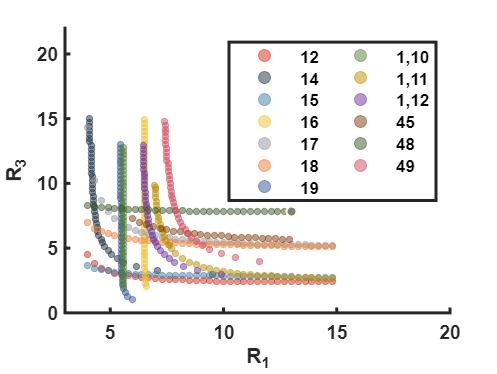


scatter(x13,y13,10,'markerfacecolor',[210, 74, 93]/256,...
        'markeredgecolor',[210, 74, 93]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','49')

set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
